# 彩色图、灰度图和二值化

## RGB分离与合并

pepper = imread('peppers.png')

pepper = 384×512×3 uint8 数组
pepper(:,:,1) =

    62    63    63    65    66    63    61    63    63    64    64    61    65    64    61    62    63    65    65    64    61    64    65    64    66    71    67    65    64    62    68    68    70    70    71    70    68    74    74    70    70    71    71    72    74    70    69    70    67    67    67    69    69    66    67    67    71    70    69    67    68    71    69    70    71    71    71    70    67    68    67    60    57    56    51    46    45    51    54    54    55    58    54    54    57    58    60    60    58    59    57    60    63    67    70    69    70    70    69    71    70    67    68    69    66    67    68    66    67    64    63    65    66    66    65    62    62    66    66    64    63    64    62    65    67    61    64    64    65    65    62    61    65    68    67    65    70    70    65    66    68    68    67    70    70    72    70    70    70    68    70    71    71    71    68    71    73    71    69 

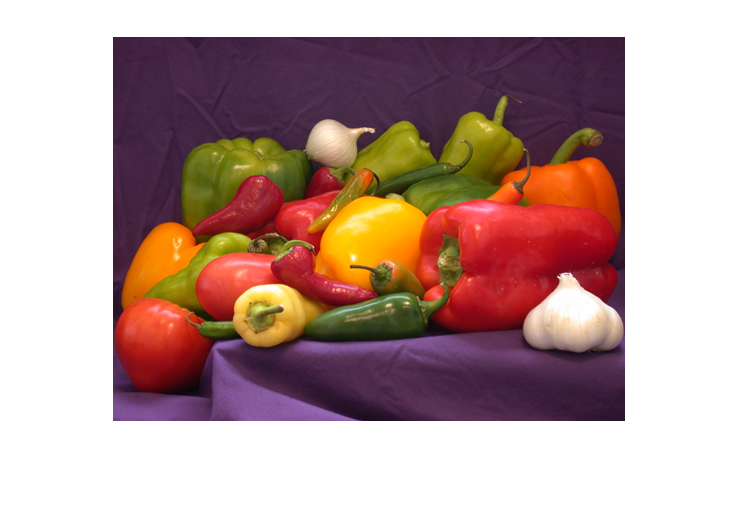

imshow(pepper)

### 分离

R = pepper(:, :, 1)

R = 384×512 uint8 矩阵
   62   63   63   65   66   63   61   63   63   64   64   61   65   64   61   62   63   65   65   64   61   64   65   64   66   71   67   65   64   62   68   68   70   70   71   70   68   74   74   70   70   71   71   72   74   70   69   70   67   67
   63   61   59   64   63   60   61   64   64   63   63   65   65   64   63   63   63   64   62   61   65   63   62   65   66   72   71   70   66   65   70   68   68   69   68   69   67   73   74   71   69   68   70   74   73   71   72   69   63   63
   65   63   63   66   66   62   60   66   64   64   64   67   68   64   61   66   66   64   66   65   64   62   59   61   65   69   66   64   67   69   70   70   69   69   68   68   69   70   69   67   68   68   66   67   71   73   68   70   67   64
   63   67   67   63   64   62   63   68   67   67   66   64   65   68   63   65   66   67   67   64   64   64   62   67   69   72   68   67   70   69   69   68   69   67   66   68   70   68   66   65   67   70   69   68   69 

G = pepper(:, :, 2)

G = 384×512 uint8 矩阵
   29   31   34   30   27   31   31   30   30   31   30   30   30   32   31   30   30   32   32   29   29   30   29   30   30   31   33   33   35   32   31   35   31   31   33   34   33   37   37   36   36   37   36   34   35   34   34   35   34   32
   31   31   32   30   28   31   31   32   31   31   30   30   30   30   31   32   32   33   31   32   33   32   30   33   32   32   37   36   37   34   31   33   32   32   33   35   34   34   34   37   39   36   36   37   37   34   35   35   35   31
   29   30   31   30   31   31   30   31   32   32   31   31   32   32   34   32   32   32   30   32   35   35   33   33   33   34   37   36   36   34   32   35   34   34   35   36   38   35   35   37   38   36   34   35   36   36   36   36   34   31
   29   29   31   31   31   32   33   31   32   33   32   32   32   34   35   35   32   32   30   33   35   34   32   33   32   32   34   35   36   35   36   37   36   35   34   37   38   36   36   35   35   34   33   34   38 

B = pepper(:, :, 3)

B = 384×512 uint8 矩阵
   64   64   64   60   59   62   62   61   59   58   61   58   56   59   59   60   62   64   61   58   57   56   58   61   61   66   67   63   62   62   64   66   65   63   65   68   67   69   69   69   70   67   67   69   70   70   67   65   63   65
   62   64   64   60   59   61   62   62   63   60   62   58   56   60   63   61   62   61   60   63   62   58   60   65   65   66   66   65   67   68   69   68   67   62   60   66   68   68   67   69   71   68   68   68   68   71   72   66   64   63
   60   62   63   61   61   64   63   63   61   64   65   63   61   60   63   65   67   62   60   63   66   65   62   64   67   66   67   66   67   71   73   69   66   66   68   68   69   69   68   66   65   67   67   67   71   70   69   71   66   64
   62   63   63   60   62   62   62   62   64   65   65   66   63   63   63   68   65   63   61   63   63   62   62   66   64   66   68   66   67   68   70   69   66   65   65   67   69   69   69   67   66   67   67   69   72 

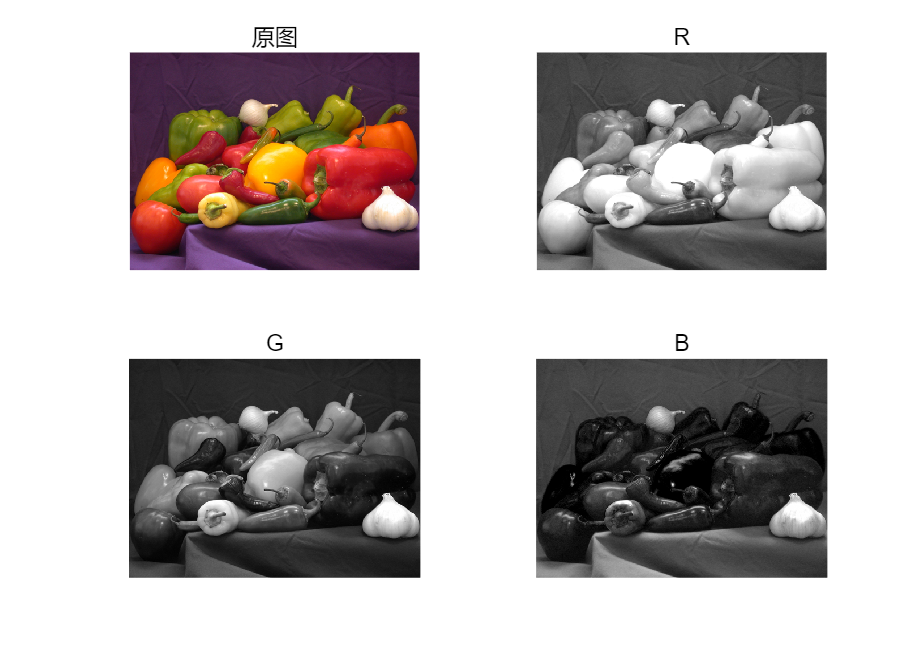

subplot(2,2,1)
imshow(pepper)
title("原图")
subplot(2,2,2)
imshow(R)
title("R")
subplot(2,2,3)
imshow(G)
title("G")
subplot(2,2,4)
imshow(B)
title("B")

### 合并

rgb(:, :, 1) = R

rgb = 384×512×3 uint8 数组
rgb(:,:,1) =

    62    63    63    65    66    63    61    63    63    64    64    61    65    64    61    62    63    65    65    64    61    64    65    64    66    71    67    65    64    62    68    68    70    70    71    70    68    74    74    70    70    71    71    72    74    70    69    70    67    67    67    69    69    66    67    67    71    70    69    67    68    71    69    70    71    71    71    70    67    68    67    60    57    56    51    46    45    51    54    54    55    58    54    54    57    58    60    60    58    59    57    60    63    67    70    69    70    70    69    71    70    67    68    69    66    67    68    66    67    64    63    65    66    66    65    62    62    66    66    64    63    64    62    65    67    61    64    64    65    65    62    61    65    68    67    65    70    70    65    66    68    68    67    70    70    72    70    70    70    68    70    71    71    71    68    71    73    71    69    70 

rgb(:, :, 2) = G

rgb = 384×512×3 uint8 数组
rgb(:,:,1) =

    62    63    63    65    66    63    61    63    63    64    64    61    65    64    61    62    63    65    65    64    61    64    65    64    66    71    67    65    64    62    68    68    70    70    71    70    68    74    74    70    70    71    71    72    74    70    69    70    67    67    67    69    69    66    67    67    71    70    69    67    68    71    69    70    71    71    71    70    67    68    67    60    57    56    51    46    45    51    54    54    55    58    54    54    57    58    60    60    58    59    57    60    63    67    70    69    70    70    69    71    70    67    68    69    66    67    68    66    67    64    63    65    66    66    65    62    62    66    66    64    63    64    62    65    67    61    64    64    65    65    62    61    65    68    67    65    70    70    65    66    68    68    67    70    70    72    70    70    70    68    70    71    71    71    68    71    73    71    69    70 

rgb(:, :, 3) = B

rgb = 384×512×3 uint8 数组
rgb(:,:,1) =

    62    63    63    65    66    63    61    63    63    64    64    61    65    64    61    62    63    65    65    64    61    64    65    64    66    71    67    65    64    62    68    68    70    70    71    70    68    74    74    70    70    71    71    72    74    70    69    70    67    67    67    69    69    66    67    67    71    70    69    67    68    71    69    70    71    71    71    70    67    68    67    60    57    56    51    46    45    51    54    54    55    58    54    54    57    58    60    60    58    59    57    60    63    67    70    69    70    70    69    71    70    67    68    69    66    67    68    66    67    64    63    65    66    66    65    62    62    66    66    64    63    64    62    65    67    61    64    64    65    65    62    61    65    68    67    65    70    70    65    66    68    68    67    70    70    72    70    70    70    68    70    71    71    71    68    71    73    71    69    70 

imshow(rgb)

## 彩色图转灰度图

% 计算R、G、B的加权和，转换为灰度值
pepper_gray = rgb2gray(pepper)

pepper_gray = 384×512 uint8 矩阵
   43   44   46   44   42   44   44   43   43   44   44   42   43   45   43   43   44   46   45   43   42   43   43   44   44   47   47   46   47   44   46   48   47   46   48   49   47   52   52   50   50   51   50   49   51   49   48   49   47   46
   44   44   44   44   42   43   44   45   45   44   44   44   43   44   44   45   45   45   44   44   46   44   43   46   46   48   50   49   49   47   47   47   47   46   47   49   48   50   50   51   52   49   50   52   51   49   50   49   47   44
   43   44   44   44   45   44   43   45   45   45   45   45   46   45   45   46   46   45   44   45   47   46   44   45   46   48   49   48   49   49   48   49   48   48   49   49   51   49   49   49   50   49   47   48   50   51   49   50   48   45
   43   44   45   44   44   44   45   46   46   47   46   45   45   47   47   48   46   46   45   46   47   46   44   47   47   48   48   48   50   49   50   50   49   48   47   50   51   49   49   48   48   49   48 

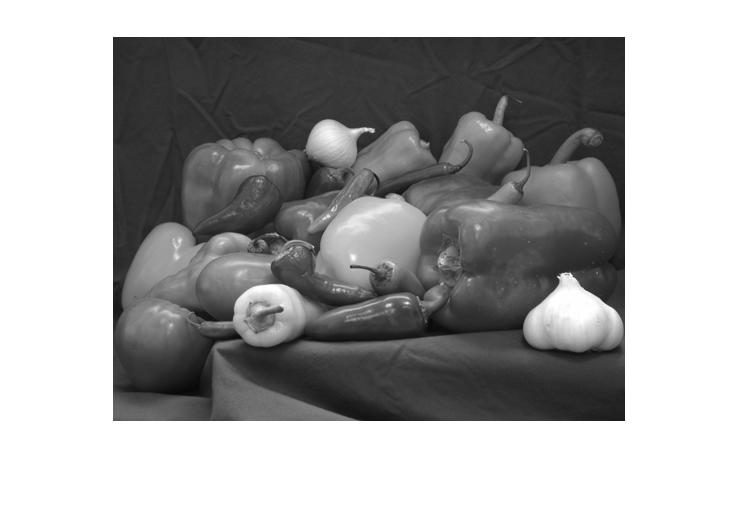

imshow(pepper_gray)

## 二值化

pepper_gray = rgb2gray(pepper)

pepper_gray = 384×512 uint8 矩阵
   43   44   46   44   42   44   44   43   43   44   44   42   43   45   43   43   44   46   45   43   42   43   43   44   44   47   47   46   47   44   46   48   47   46   48   49   47   52   52   50   50   51   50   49   51   49   48   49   47   46
   44   44   44   44   42   43   44   45   45   44   44   44   43   44   44   45   45   45   44   44   46   44   43   46   46   48   50   49   49   47   47   47   47   46   47   49   48   50   50   51   52   49   50   52   51   49   50   49   47   44
   43   44   44   44   45   44   43   45   45   45   45   45   46   45   45   46   46   45   44   45   47   46   44   45   46   48   49   48   49   49   48   49   48   48   49   49   51   49   49   49   50   49   47   48   50   51   49   50   48   45
   43   44   45   44   44   44   45   46   46   47   46   45   45   47   47   48   46   46   45   46   47   46   44   47   47   48   48   48   50   49   50   50   49   48   47   50   51   49   49   48   48   49   48 

bw = imbinarize(pepper_gray, "adaptive", "ForegroundPolarity","bright", "Sensitivity",0.55)

bw = 384×512 logical 数组
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   0   1   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   0   0   0   0   0   0   0   0   1   1   1   1   0   1   1   1   0   1   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   1   1   0   0   0   0   0   0   1   0   0   0   1   0   0   0   1   1   0   1   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   0   0   0   1   1   0   0   0   0   0   0   0   1   1   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   0   1   0   0   0   0   0   0   0   0   0   0

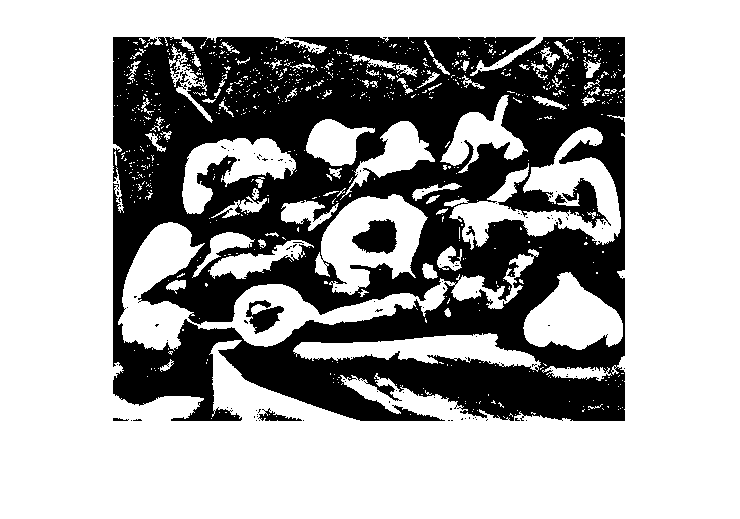

imshow(bw)

I = imread('printedtext.png')

I = 918×1632 uint8 矩阵
   12   12   12   13   13   12   12   12   11   11   11   12   12   11   11   12   13   14   14   13   15   14   13   14   14   14   14   13   13   12   12   12   12   12   12   12   12   12   13   13   13   12   12   13   12   12   13   13   13   13
   13   13   13   13   12   12   12   12   12   13   12   12   12   11   10   11   13   14   13   12   14   14   13   13   14   14   12   12   11   11   12   12   13   13   13   13   13   13   13   13   12   13   13   13   12   13   13   13   14   14
   14   13   13   12   10   10   11   12   12   13   13   12   11   10   11   11   13   13   12   12   13   13   12   12   13   13   13   13   12   12   12   12   13   13   13   13   13   13   13   12   11   12   12   12   12   13   13   13   14   14
   13   13   12   11   10   10   11   12   12   12   13   13   11   10   11   12   12   13   13   13   12   12   12   12   12   13   13   13   13   12   12   12   12   13   13   13   12   13   13   12   12   13   13   13   13

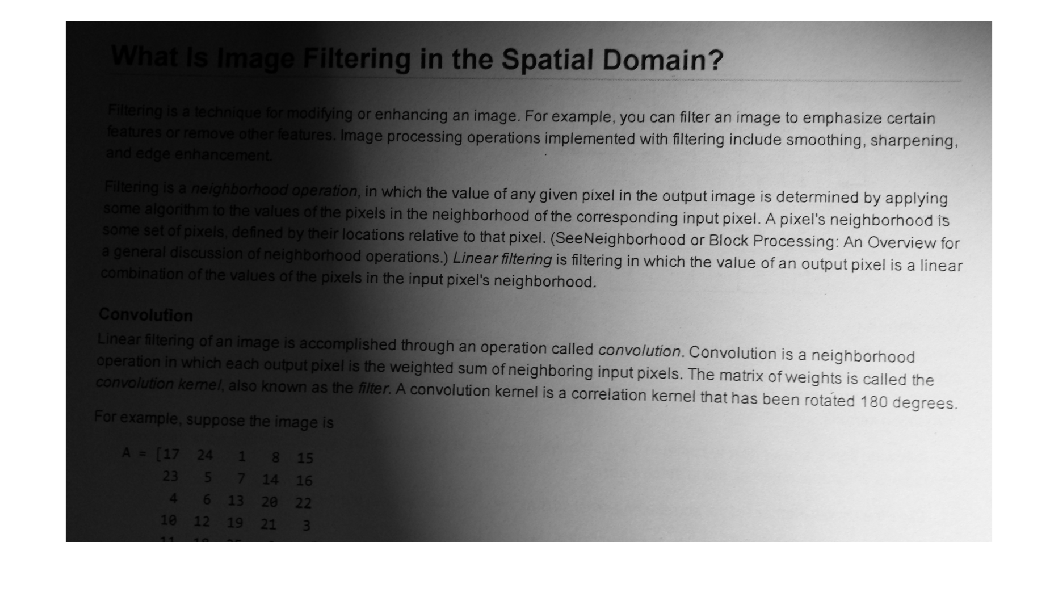

imshow(I)

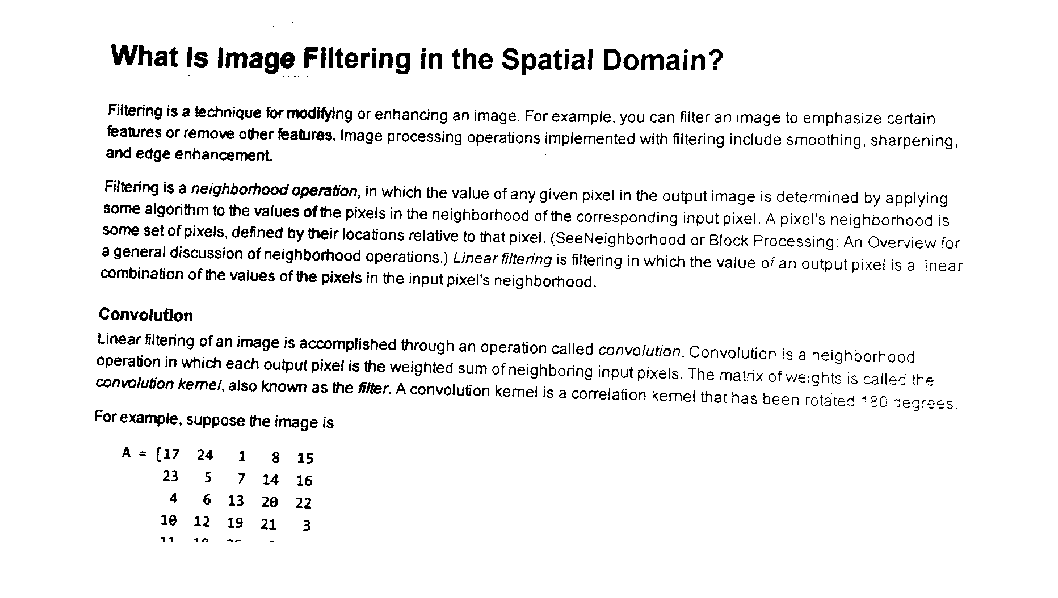

bw2 = imbinarize(I, "adaptive", "ForegroundPolarity","dark", "Sensitivity",0.3);
imshow(bw2)